clc, clearvars;
v = VideoReader("shuttle.avi");

firstFr = readFrame(v);
firstFrGray = rgb2gray(firstFr);
firstFrMask = firstFrGray > 245;
firstTrPx = nnz(firstFrMask)

firstTrPx = 520

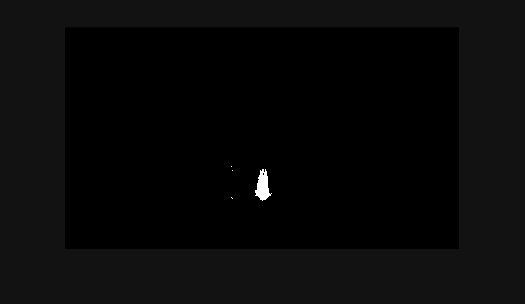

imshow(firstFrMask);

v.CurrentTime = 0;

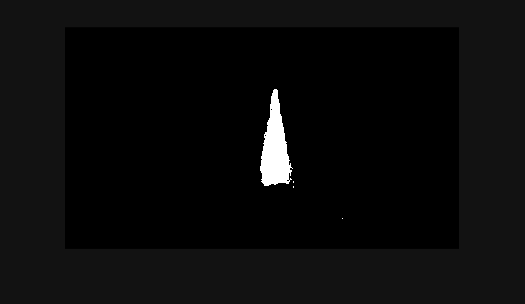

% Play the video
%v.CurrentTime = (118-1)/v.FrameRate;
lastFr = read(v, 118);
lastFrGray = rgb2gray(lastFr);
lastFrMask = lastFrGray > 245;
imshow(lastFrMask);

lastTrPx = nnz(lastFrMask)

lastTrPx = 3072

diff = lastTrPx-firstTrPx

diff = 2552